# Overview Figure: RCEW & Wolverine Glacier

%% Code to plot a figure including subplot overview maps of Landsat images 
% overlain by ICESat-2 tracks color-coded by season (customized for RCEW &
% Wolverine Glacier but could be modified for more sites)

## Initialize

clear all; close all; warning off;
addpath('/users/ellynenderlin/Research/miscellaneous/general-code/','/users/ellynenderlin/Research/miscellaneous/general-code/cmocean/');
addpath('/Users/ellynenderlin/Research/NASA_CryoIdaho/ICESat2-snow-code/');

%make figure folder as necessary
root_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/'; cd(root_path);
if exist('figures','dir') ~= 7; mkdir('figures'); end
figure_path = [root_path,'figures/'];

%RCEW data
RCEW_path = [root_path,'mountains/RCEW/']; %include trailing /
RCEWS = shaperead([RCEW_path,'ROIs/RCEW-outline_WGS84-UTM11N.shp']); % outline in UTM coordinates
IDstate = shaperead([RCEW_path,'ROIs/Idaho-shapefile.shp']);
[RCEWlat,RCEWlon]=utm2ll(nanmean(RCEWS.X),nanmean(RCEWS.Y),11); %RCEWlon = RCEWlon + 360;
[RCEWx,RCEWy] = wgs2ps(RCEWlon,RCEWlat,'StandardParallel',52,'StandardMeridian',-130); 

%Wolverine data
WG_path = [root_path,'glaciers/Wolverine/']; %include trailing /
glims = shaperead([WG_path,'ROIs/Wolverine-2018-outline-UTM06N.shp']); % outline in UTM coordinates
WGS.X = glims.X; WGS.Y = glims.Y; % note: 2d version of the glims polygon made in QGIS... Matlab's shaperead can't handle a PolygonZ geometry
clear glims;
catchment = shaperead([WG_path,'ROIs/WG_catchment_2021.shp']); %need larger catchment for coregistration of glacier sites
[catchx,catchy] = wgs2utm(catchment.Y,catchment.X); clear catchment; catchment.X = catchx; catchment.Y = catchy; clear catchx catchy;
AKstate = shaperead([WG_path,'ROIs/Alaska-shapefile.shp']);
[WGlat,WGlon]=utm2ll(nanmean(WGS.X),nanmean(WGS.Y),6); %WGlon = WGlon + 360;
[WGx,WGy] = wgs2ps(WGlon,WGlat,'StandardParallel',52,'StandardMeridian',-130); 

%day of year info for date conversion
modays = [31 28 31 30 31 30 31 31 30 31 30 31]; cumdays = [0 cumsum(modays(1:end-1))];
leap_modays = [31 29 31 30 31 30 31 31 30 31 30 31]; leap_cumdays = [0 cumsum(leap_modays(1:end-1))];

%colorblind-friendly seasonal colors
seas_cmap = [5,113,176; 202,0,32]/255;

## Load Landsat images & ICESat-2 tracks

%RCEW
%load the Landsat image
cd(RCEW_path);
Landsat = dir('L*T1'); cd(Landsat(1).name);
[B,Ref] = readgeoraster([Landsat(1).name,'_B2.tif']); Bdoub = im2double(B); clear B;
[G,~] = readgeoraster([Landsat(1).name,'_B3.tif']); Gdoub = im2double(G); clear G;
[R,~] = readgeoraster([Landsat(1).name,'_B4.tif']); Rdoub = im2double(R); clear R;
%convert spacing referencing info to coordinate vectors
RCEW_imx = Ref.XWorldLimits(1):Ref.SampleSpacingInWorldX:Ref.XWorldLimits(2);
RCEW_imy = Ref.YWorldLimits(2):-Ref.SampleSpacingInWorldY:Ref.YWorldLimits(1);
%concatenate image and create colormap
Bdoub(Bdoub==0) = NaN; Gdoub(Gdoub==0) = NaN; Rdoub(Rdoub==0) = NaN; 
RGB = cat(3,Rdoub,Gdoub,Bdoub); 
clear Landsat *_scaled Ref;
%load the ICESat-2 transects
cd([RCEW_path,'csvs/']);
RCEWT = readtable('RCEW-ICESat2-ATL08-params.csv');
%identify data within the catchment
[xgrid,ygrid] = meshgrid(RCEW_imx,RCEW_imy);
[in,~] = inpolygon(xgrid,ygrid,RCEWS.X(1:end-1),RCEWS.Y(1:end-1));
RCEWxmax = max(max(xgrid(in==1))); RCEWxmin = min(min(xgrid(in==1))); 
RCEWymax = max(max(ygrid(in==1))); RCEWymin = min(min(ygrid(in==1)));
%stretch the image using just data from the cropped area
RCEWXcrop = RCEW_imx(min([find(RCEW_imx==RCEWxmin) find(RCEW_imx==RCEWxmax)]):max([find(RCEW_imx==RCEWxmin) find(RCEW_imx==RCEWxmax)]));
RCEWYcrop = RCEW_imy(min([find(RCEW_imy==RCEWymin) find(RCEW_imy==RCEWymax)]):max([find(RCEW_imy==RCEWymin) find(RCEW_imy==RCEWymax)]));
RGBcrop = RGB(min([find(RCEW_imy==RCEWymin) find(RCEW_imy==RCEWymax)]):max([find(RCEW_imy==RCEWymin) find(RCEW_imy==RCEWymax)]),...
    min([find(RCEW_imx==RCEWxmin) find(RCEW_imx==RCEWxmax)]):max([find(RCEW_imx==RCEWxmin) find(RCEW_imx==RCEWxmax)]),...
    :);
RGBadjust = imadjustn(RGBcrop);
% [RCEW_IND,RCEW_map] = rgb2ind(RGBadjust,2^12); 
RCEW_RGB = RGBadjust;
clear xgrid ygrid in RGB*;


%WOLVERINE
%load the Landsat image
cd(WG_path);
Landsat = dir('L*T1'); cd(Landsat(1).name);
[B,Ref] = readgeoraster([Landsat(1).name,'_B2.tif']); Bdoub = im2double(B); clear B;
[G,~] = readgeoraster([Landsat(1).name,'_B3.tif']); Gdoub = im2double(G); clear G;
[R,~] = readgeoraster([Landsat(1).name,'_B4.tif']); Rdoub = im2double(R); clear R;
%convert spacing referencing info to coordinate vectors
WG_imx = Ref.XWorldLimits(1):Ref.SampleSpacingInWorldX:Ref.XWorldLimits(2);
WG_imy = Ref.YWorldLimits(2):-Ref.SampleSpacingInWorldY:Ref.YWorldLimits(1);
%concatenate image
Bdoub(Bdoub==0) = NaN; Gdoub(Gdoub==0) = NaN; Rdoub(Rdoub==0) = NaN; 
RGB = cat(3,Rdoub,Gdoub,Bdoub); 
clear Landsat *_scaled Ref;
%load the ICESat-2 transects
cd([WG_path,'csvs/']);
WGT = readtable('WG-ICESat2-ATL06-params.csv');
%identify data within the catchment
[xgrid,ygrid] = meshgrid(WG_imx,WG_imy);
[in,~] = inpolygon(xgrid,ygrid,catchment.X(1:end-1),catchment.Y(1:end-1));
WGxmax = max(max(xgrid(in==1))); WGxmin = min(min(xgrid(in==1))); 
WGymax = max(max(ygrid(in==1))); WGymin = min(min(ygrid(in==1)));
%stretch the image using just data from the cropped area
WGXcrop = WG_imx(min([find(WG_imx==WGxmin) find(WG_imx==WGxmax)]):max([find(WG_imx==WGxmin) find(WG_imx==WGxmax)]));
WGYcrop = WG_imy(min([find(WG_imy==WGymin) find(WG_imy==WGymax)]):max([find(WG_imy==WGymin) find(WG_imy==WGymax)]));
RGBcrop = RGB(min([find(WG_imy==WGymin) find(WG_imy==WGymax)]):max([find(WG_imy==WGymin) find(WG_imy==WGymax)]),...
    min([find(WG_imx==WGxmin) find(WG_imx==WGxmax)]):max([find(WG_imx==WGxmin) find(WG_imx==WGxmax)]),...
    :);
RGBadjust = imadjustn(RGBcrop);
% [WG_IND,WG_map] = rgb2ind(RGBadjust,2^12); 
WG_RGB = RGBadjust;
clear xgrid ygrid in RGB*;


## Create Maps

%create figure
figure; set(gcf,'position',[0 0 800 800],'DefaultTextFontSize', 16);

%RCEW
RCEWsub = subplot(1,2,1);
% imagesc(RCEW_imx,RCEW_imy,RCEW_IND); colormap(RCEW_map); 
image(RCEWXcrop,RCEWYcrop,RCEW_RGB);
axis xy equal; hold on;
set(gca,'fontsize',16,'xlim',[RCEWxmin RCEWxmax],'ylim',[RCEWymin RCEWymax]);
%add the shapefile outline
plot([RCEWS.X RCEWS.X(1)],[RCEWS.Y RCEWS.Y(1)],'-y','linewidth',2); hold on;
%add the ICESat-2 transects
beams = RCEWT.beam; dates = RCEWT.date; unique_dates = unique(dates);
fprintf('%i unique dates \n',length(unique_dates));

23 unique dates 


for j = 1:length(unique_dates)
    if mod(floor(unique_dates(j)),4) ~= 0
        days = sum(leap_modays)*(unique_dates(j)-floor(unique_dates(j)));
         mo = uint8(find(leap_cumdays<days,1,'last')); day = uint8(days - leap_cumdays(mo));
    else
        days = sum(modays)*(unique_dates(j)-floor(unique_dates(j)));
        mo = uint8(find(cumdays<days,1,'last')); day = uint8(days - cumdays(mo));
    end
    fprintf('%4i/%2i/%2i: %5i footprints \n',floor(unique_dates(j)),mo,day,length(find(dates == unique_dates(j))));
    clear days mo day;
end

2018/11/26:    91 footprints 
2019/ 2/25:    30 footprints 
2019/ 8/26:   962 footprints 
2019/ 8/28:  1199 footprints 
2019/11/25:   182 footprints 
2020/ 1/26:   763 footprints 
2020/ 2/23:  1251 footprints 
2020/ 2/26:   711 footprints 
2020/ 5/25:   830 footprints 
2020/ 8/23:   139 footprints 
2020/ 8/26:   507 footprints 
2020/11/22:   296 footprints 
2020/12/21:   430 footprints 
2021/ 1/23:    64 footprints 
2021/ 2/21:   529 footprints 
2021/ 2/23:  1132 footprints 
2021/ 5/24:    39 footprints 
2021/ 7/23:   680 footprints 
2021/ 8/21:    23 footprints 
2021/ 8/24:   498 footprints 
2021/ 9/22:  1021 footprints 
2021/11/20:   521 footprints 
2021/11/23:  1100 footprints 


[~,unique_refs] = unique([num2str(dates),string(beams)],'rows');
unique_refs = sort(unique_refs);
for j = 1:length(unique_refs)
    if RCEWT.season(unique_refs(j)) == 3; seas_color = seas_cmap(2,:); else seas_color = seas_cmap(1,:); end
    if j < length(unique_refs)
        plot([RCEWT.Easting(unique_refs(j)), RCEWT.Easting(unique_refs(j+1)-1)],[RCEWT.Northing(unique_refs(j)),RCEWT.Northing(unique_refs(j+1)-1)],'-','color',seas_color,'linewidth',2);
    else
        plot([RCEWT.Easting(unique_refs(j)), RCEWT.Easting(end)],[RCEWT.Northing(unique_refs(j)),RCEWT.Northing(end)],'-','color',seas_color,'linewidth',2);
    end
end
set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
clear beams dates unique_dates unique_refs inset_ax nanrefs;
text(min(get(gca,'xlim'))+0.05*range(get(gca,'xlim')),min(get(gca,'ylim'))+0.03*range(get(gca,'ylim')),'b) Reynolds Creek','fontsize',16,'color','w');
drawnow;

%WOLVERINE
WGsub = subplot(1,2,2);
% imagesc(WG_imx,WG_imy,WG_IND); colormap(WG_map); 
image(WGXcrop,WGYcrop,WG_RGB);
axis xy equal; hold on;
set(gca,'fontsize',16,'xlim',[WGxmin WGxmax],'ylim',[WGymin WGymax]);
%add the shapefile outline
plot([WGS.X WGS.X(1)],[WGS.Y WGS.Y(1)],'-y','linewidth',2); hold on;
%add the ICESat-2 transects
beams = WGT.beam; dates = WGT.date; unique_dates = unique(dates);
fprintf('%i unique dates \n',length(unique_dates));

18 unique dates 


for j = 1:length(unique_dates)
    if mod(floor(unique_dates(j)),4) ~= 0
        days = sum(leap_modays)*(unique_dates(j)-floor(unique_dates(j)));
         mo = uint8(find(leap_cumdays<days,1,'last')); day = uint8(days - leap_cumdays(mo));
    else
        days = sum(modays)*(unique_dates(j)-floor(unique_dates(j)));
        mo = uint8(find(cumdays<days,1,'last')); day = uint8(days - cumdays(mo));
    end
    fprintf('%4i/%2i/%2i: %5i footprints \n',floor(unique_dates(j)),mo,day,length(find(dates == unique_dates(j))));
    clear days mo day;
end

2019/ 2/24:   289 footprints 
2019/ 2/26:   683 footprints 
2019/ 5/27:   488 footprints 
2019/ 8/25:   111 footprints 
2019/ 8/26:   625 footprints 
2019/11/24:   699 footprints 
2020/ 5/24:     8 footprints 
2020/11/23:   773 footprints 
2021/ 2/21:   769 footprints 
2021/ 5/21:   304 footprints 
2021/ 5/22:   195 footprints 
2021/ 6/19:    40 footprints 
2021/ 7/23:     4 footprints 
2021/ 8/22:  1029 footprints 
2021/ 9/18:   922 footprints 
2021/ 9/20:    20 footprints 
2021/10/21:   319 footprints 
2021/11/21:   131 footprints 


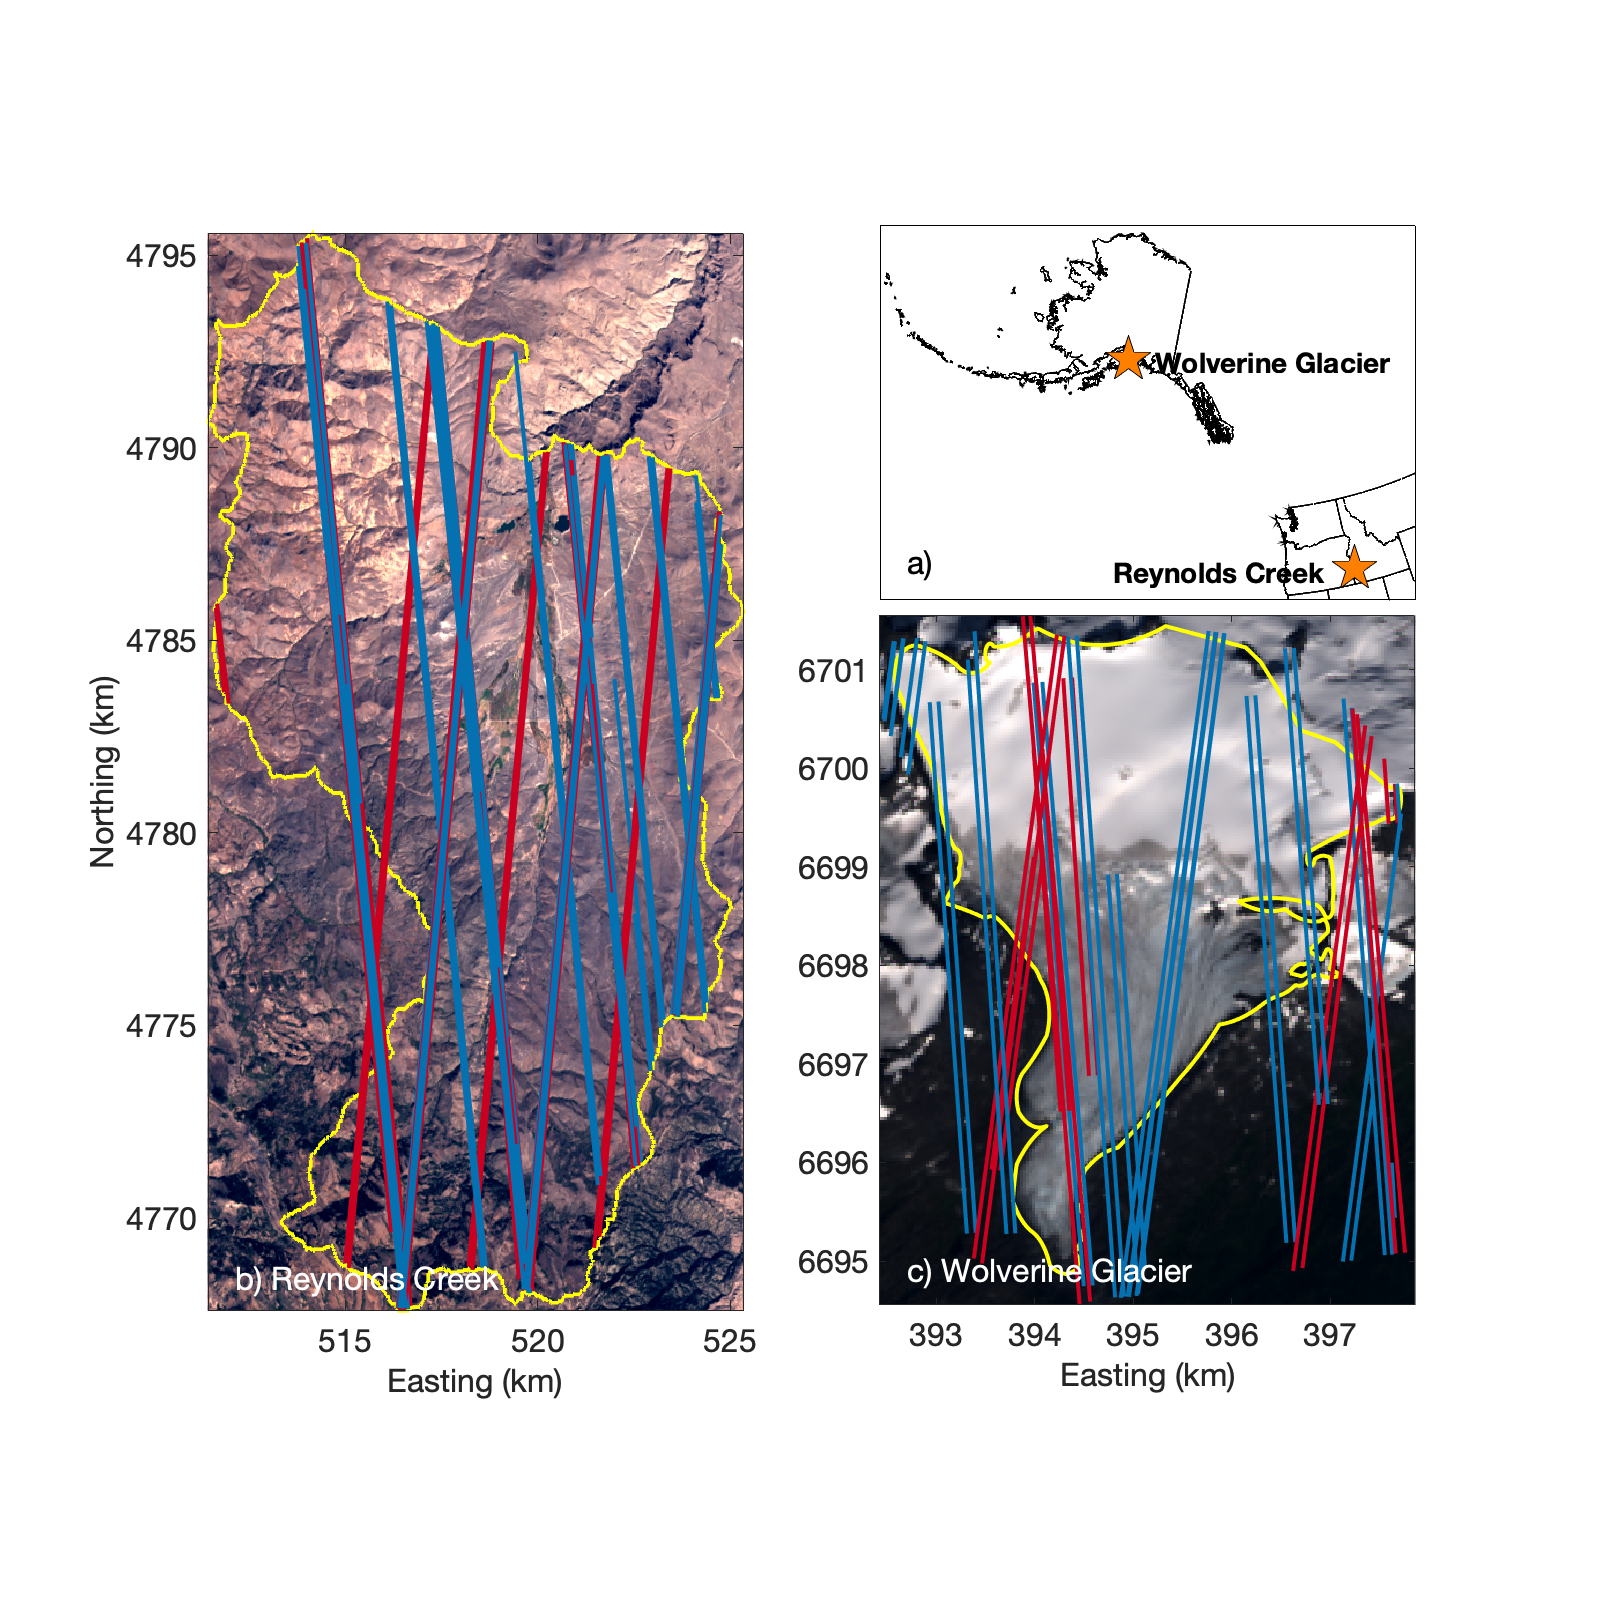

[~,unique_refs] = unique([num2str(dates),string(beams)],'rows');
unique_refs = sort(unique_refs);
for j = 1:length(unique_refs)
    if WGT.season(unique_refs(j)) == 3; seas_color = seas_cmap(2,:); else seas_color = seas_cmap(1,:); end
    if j < length(unique_refs)
        plot([WGT.Easting(unique_refs(j)), WGT.Easting(unique_refs(j+1)-1)],[WGT.Northing(unique_refs(j)),WGT.Northing(unique_refs(j+1)-1)],'-','color',seas_color,'linewidth',2);
    else
        plot([WGT.Easting(unique_refs(j)), WGT.Easting(end)],[WGT.Northing(unique_refs(j)),WGT.Northing(end)],'-','color',seas_color,'linewidth',2);
    end
end
set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
xlabel('Easting (km)','fontsize',16); 
clear beams dates unique_dates unique_refs inset_ax nanrefs;
subpos1 = get(RCEWsub,'position'); subpos2 = get(WGsub,'position');
set(WGsub,'position',[0.55 0.10 subpos2(3) 0.6]);
text(min(get(gca,'xlim'))+0.05*range(get(gca,'xlim')),min(get(gca,'ylim'))+0.05*range(get(gca,'ylim')),'c) Wolverine Glacier','fontsize',16,'color','w');
drawnow;

%overlay a state map in an open space
cd(root_path); cd('state_outlines');
state = shaperead('state.shp');
inset_ax = axes('Position', [0.55, 0.6, subpos2(3), subpos2(3)-0.05]);
for j = 1:length(state)
    [sx,sy] = wgs2ps(state(j).X,state(j).Y,'StandardParallel',52,'StandardMeridian',-130); state(j).X = sx; state(j).Y = sy; clear sx sy;
%     state(j).X(state(j).X<0) = state(j).X(state(j).X<0)+360;
    maxlat(j) = max(state(j).Y); minlat(j) = min(state(j).Y); maxlon(j) = max(state(j).X); minlon(j) = min(state(j).X); 
    nanrefs = find(isnan(state(j).X));
    for i = 1:length(nanrefs)
        if i == 1
            fill([state(j).X(1:nanrefs(i)-1) state(j).X(1)],[state(j).Y(1:nanrefs(i)-1) state(j).Y(1)],[1 1 1],'facecolor','w','edgecolor','k','linewidth',1); hold on;
        else
            fill([state(j).X(nanrefs(i-1)+1:nanrefs(i)-1) state(j).X(nanrefs(i-1)+1)],[state(j).Y(nanrefs(i-1)+1:nanrefs(i)-1) state(j).Y(nanrefs(i-1)+1)],[1 1 1],'edgecolor','k','facecolor','w','linewidth',1); hold on;
        end
    end
    clear nanrefs;
end
axis xy equal; set(gca,'xlim',[-3.3e6 1.7e6],'ylim',[-5.1e6 -1.6e6]);
set(gca,'XTick',[],'YTick',[],'color','w','XColor','k','YColor','k','box','on');
text(min(get(gca,'xlim'))+0.05*range(get(gca,'xlim')),min(get(gca,'ylim'))+0.1*range(get(gca,'ylim')),'a) ','fontsize',16);
% plot(RCEWlon,RCEWlat,'pk','markerfacecolor',[1 0.5 0],'markersize',24); hold on;
% plot(WGlon,WGlat,'pk','markerfacecolor',[1 0.5 0],'markersize',24); hold on;
plot(RCEWx,RCEWy,'pk','markerfacecolor',[1 0.5 0],'markersize',24); hold on;
text(RCEWx-2.25e6,RCEWy-0.025e6,'Reynolds Creek','fontsize',14,'fontweight','bold');
plot(WGx,WGy,'pk','markerfacecolor',[1 0.5 0],'markersize',24); hold on;
text(WGx+0.25e6,WGy-0.025e6,'Wolverine Glacier','fontsize',14,'fontweight','bold');
clear beams dates unique_dates unique_refs nanrefs;

%save!
cd(figure_path);
saveas(gcf,['ICESat2tracks-map.eps'],'epsc');